## Nika Emami - ne2213 - HW2 Machine Learning

### Question 1:

First, I load the data and initialize the x and y sets:

train_set = load('data3.mat').data;
x = train_set(:,1:2);
y = train_set(:,3);	

Next, I implement a function to perform the **Gradient Descent** algorithm as below.

First, I initialize the parameters that will be needed in the updating process. In the GD function, I run the process for the number of iterations. We know that in a linear perceptron, we use sign(z) as the activation function to calculate the predicted labels (1 or -1). Then, I compute the gradients and update the coefficients with them. I call the function as below:

num_iters = 250;
learning_rate = 0.1;
fprintf('Results for Learning Rate = 0.1:')

Results for Learning Rate = 0.1:

[coefficients, loss] = GD(x, y, num_iters, learning_rate);

Next, I implement a function to plot the evolution of the perceptron error with the number of iterations. Also, I plot the linear decision boundary on the 2D data. I call the function as below: 

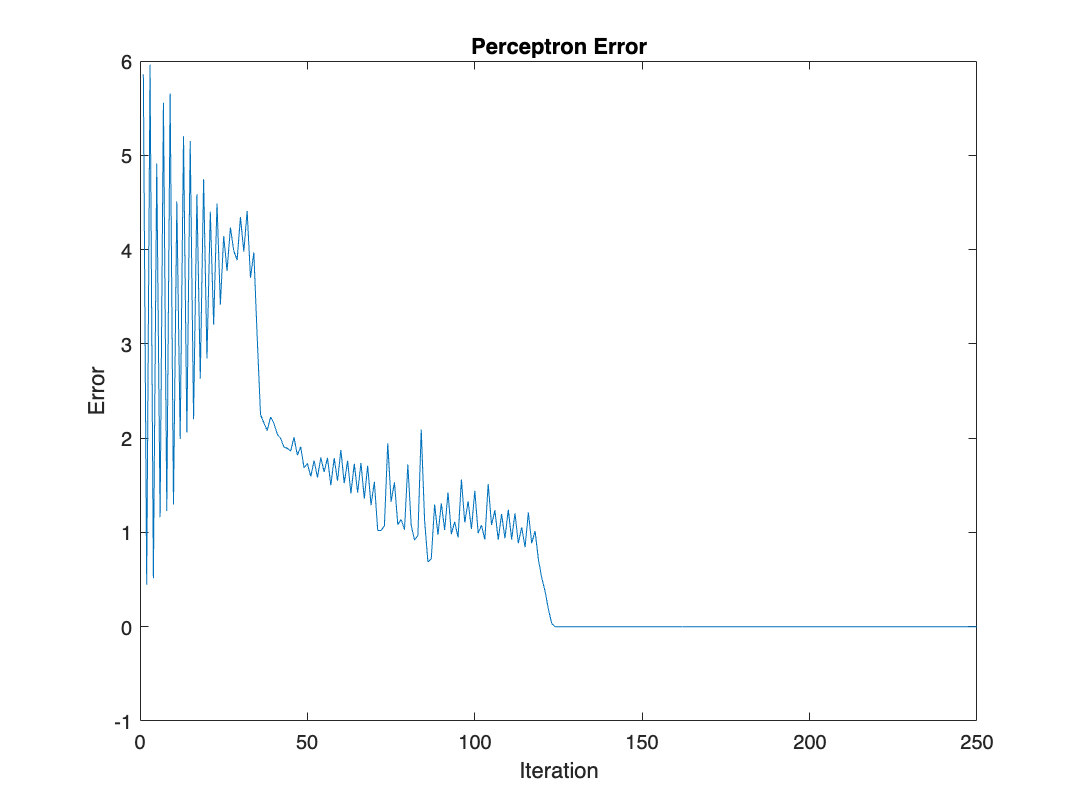

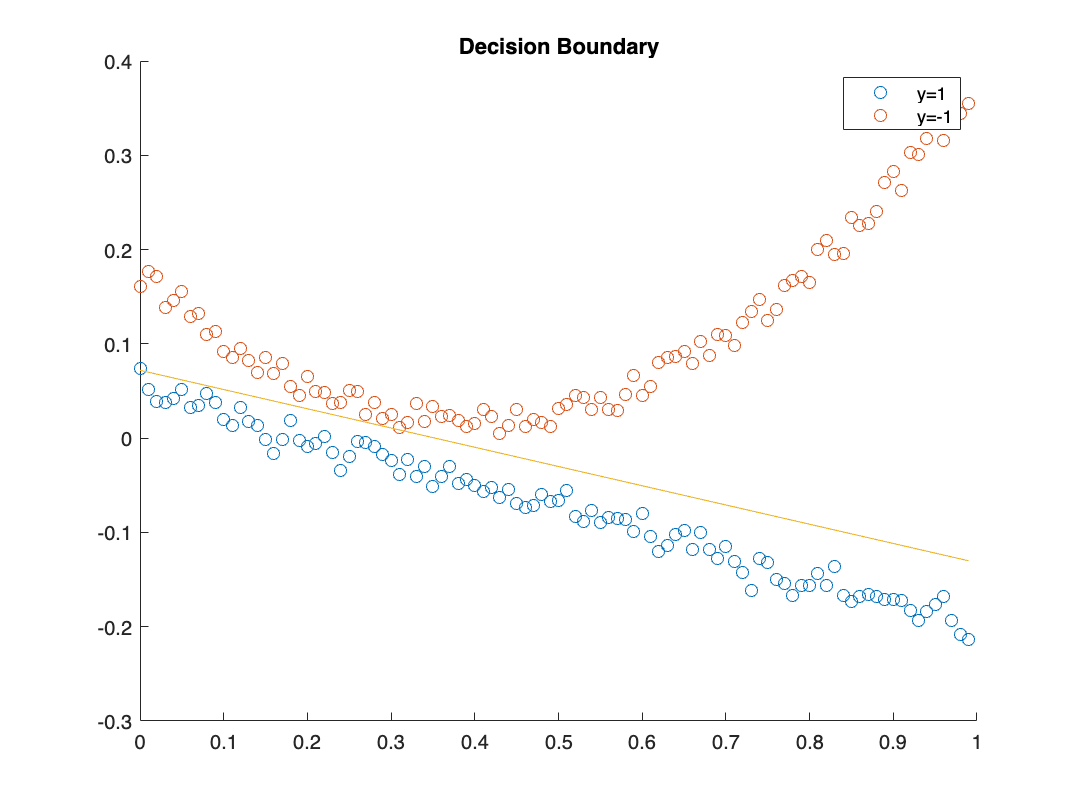

x1 = train_set(train_set(:,3)==1,1:2);
x2 = train_set(train_set(:,3)==-1,1:2);
plot_results(coefficients, loss, x1, x2);

As it can be seen, the algorithm converges and the loss leans toward 0. Also, we can see that the classifier has good results and can separate the data to a good extent.

Next, I check the algorithm with different values for the learning rate as below:

**learning_rate = 0.001:**

learning_rate = 0.001;
fprintf('Results for Learning Rate = 0.001:')

Results for Learning Rate = 0.001:

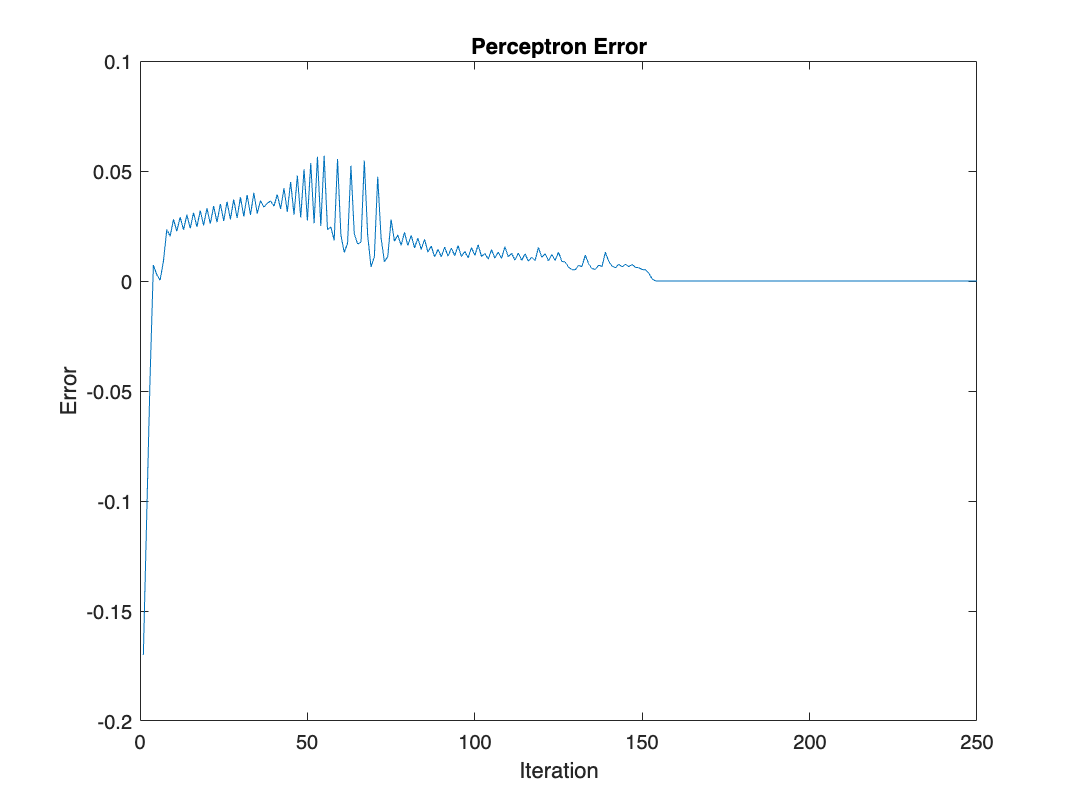

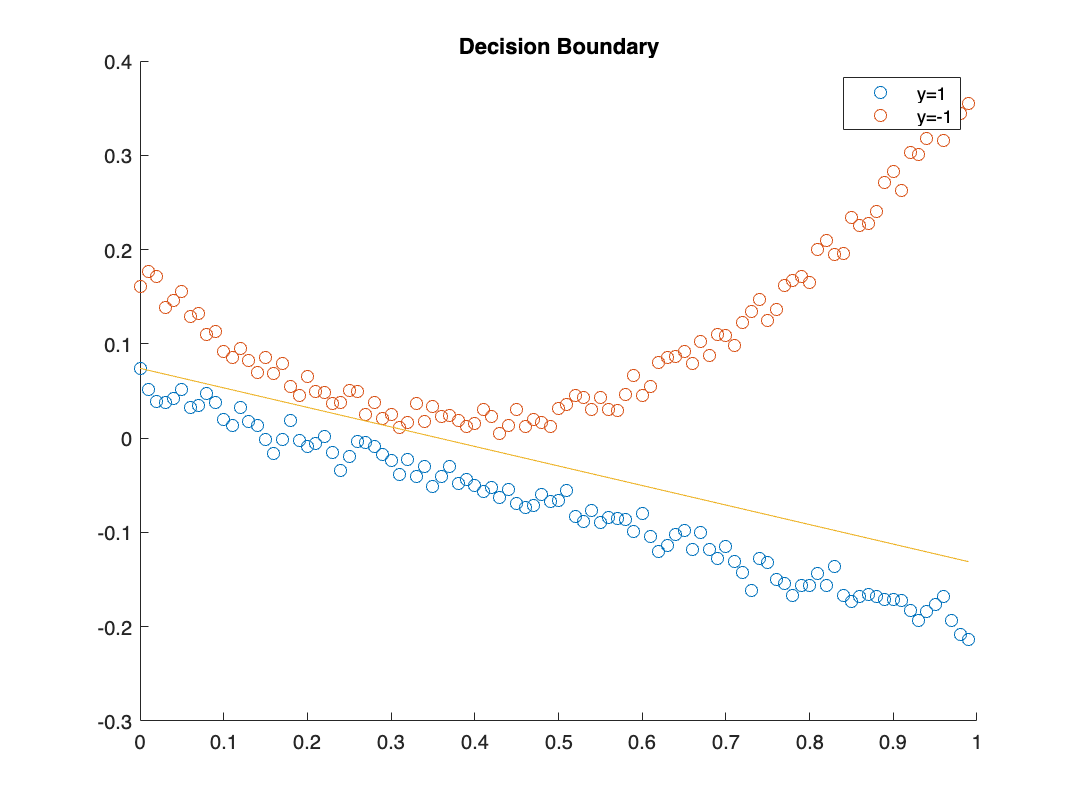

[coefficients, loss] = GD(x, y, num_iters, learning_rate); 
plot_results(coefficients, loss, x1, x2);

**learning_rate = 0.95:**

learning_rate = 0.95;
fprintf('Results for Learning Rate = 0.95:')

Results for Learning Rate = 0.95:

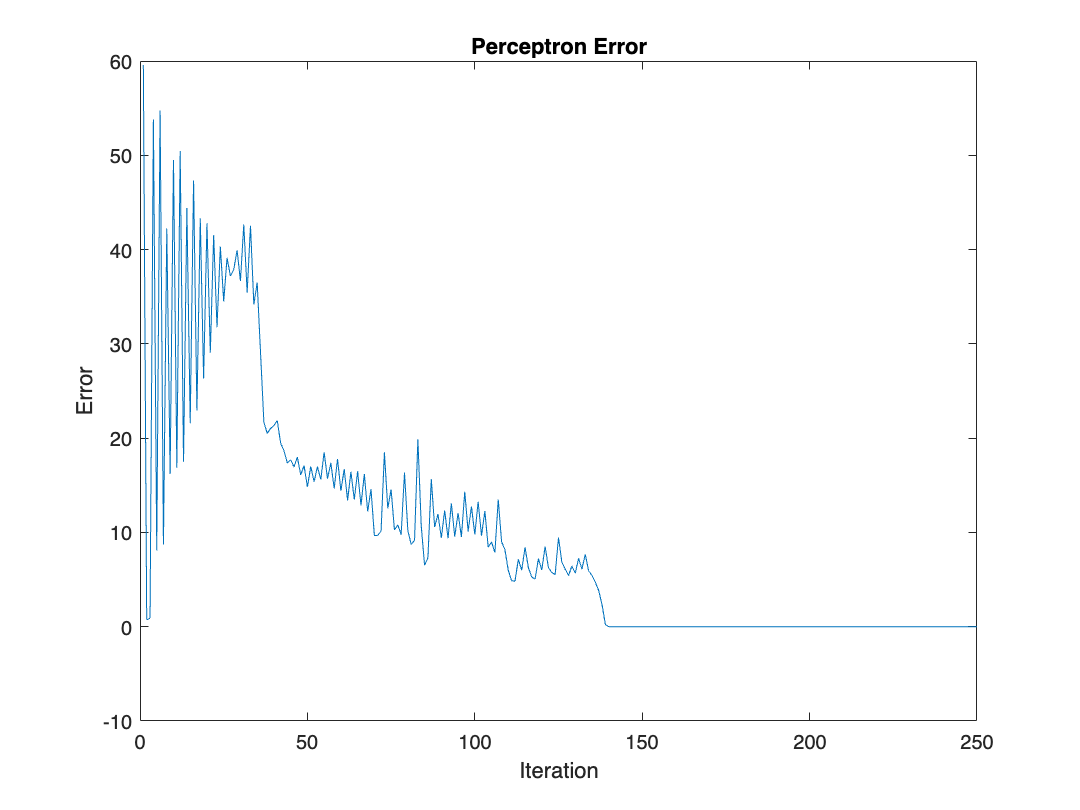

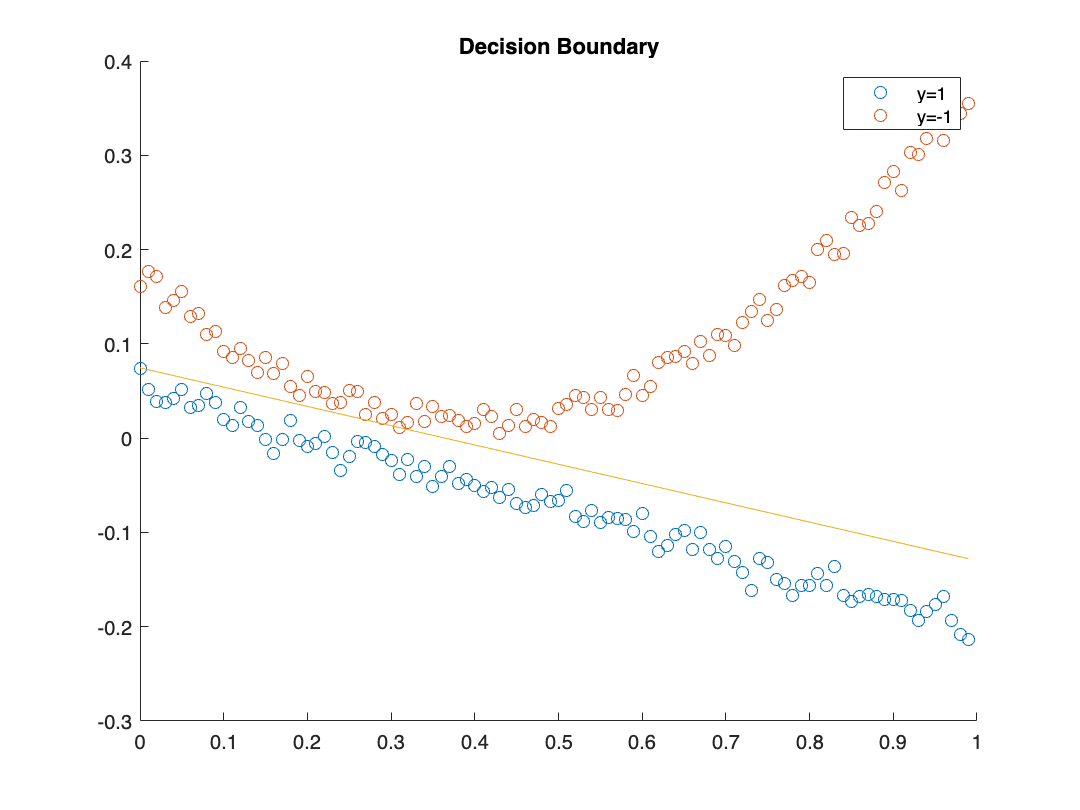

[coefficients, loss] = GD(x, y, num_iters, learning_rate); 
plot_results(coefficients, loss, x1, x2);

As it can be seen, for different values of learning rate, we have slightly different results:

It can be seen that a higher learning rate allows the algorithm to converge faster (because it takes larger steps in the parameter space.), but a lower learning rate results in a slower, but more stable convergence, and it requires more iterations to reach the minimum.

function [coefficients, loss] = GD(x, y, num_iters, learning_rate)
num_samples = length(y);
x_initials = [ones(num_samples,1),x];
coefficients = rand(length(x(1,:))+1,1);
loss = zeros(num_iters,1);

for i = 1:num_iters
    z = x_initials * coefficients;
    y_predicted = sign(z);
    wrong_predict = (y_predicted ~= y);
    gradient = -y(wrong_predict) .* x_initials(wrong_predict, :);
    coefficients = coefficients - (learning_rate * transpose(sum(gradient)));
    output = x_initials * coefficients;
    loss(i) = (1 / num_samples) * sum(y(wrong_predict) .* output(wrong_predict));
end
end

function plot_results(coefficients, loss, x1, x2)
    figure;
    plot(loss);
    title('Perceptron Error');
    xlabel('Iteration');
    ylabel('Error');

    begin_ = min(x1(:,1));
    end_ = max(x1(:,1));
    feature1 = linspace(begin_, end_, 100);
    feature2 = -(coefficients(1) + (feature1 * coefficients(2))) / coefficients(3);

    figure;
    scatter(x1(:, 1), x1(:, 2));
    hold on;
    scatter(x2(:, 1), x2(:, 2));
    plot(feature1, feature2);
    legend('y=1', 'y=-1');
    title('Decision Boundary');
    hold off;
end